# **Projeto 2 - Mecânica dos Sólidos**

## **Aula 24:** Exercício 1

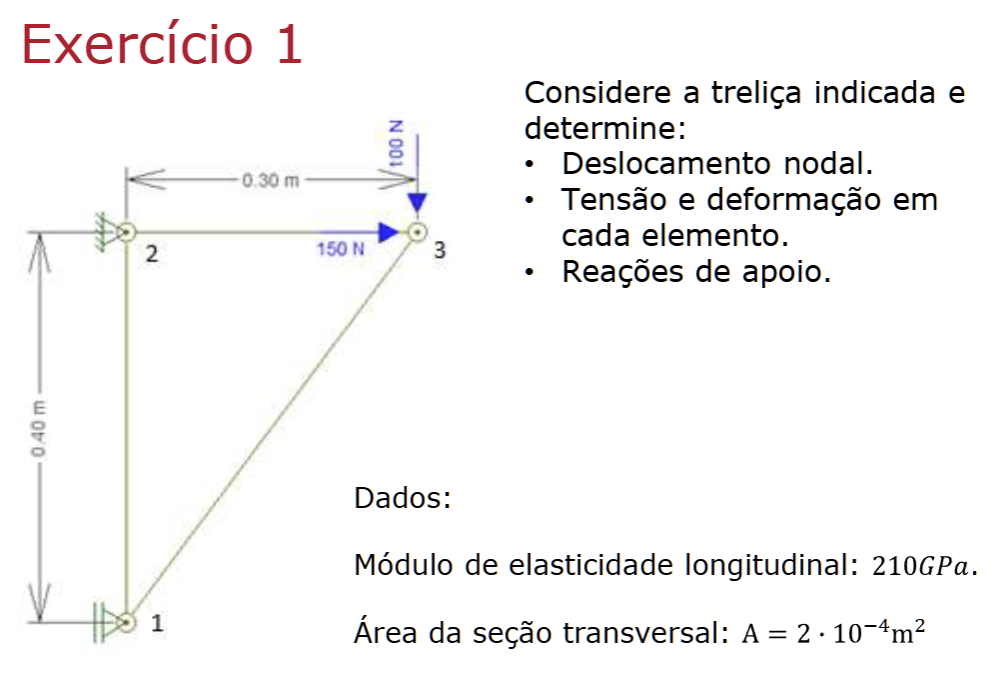

% PASSO 1: Definir a origem do sistema de referência e numerar os nós; elementos; GDL.

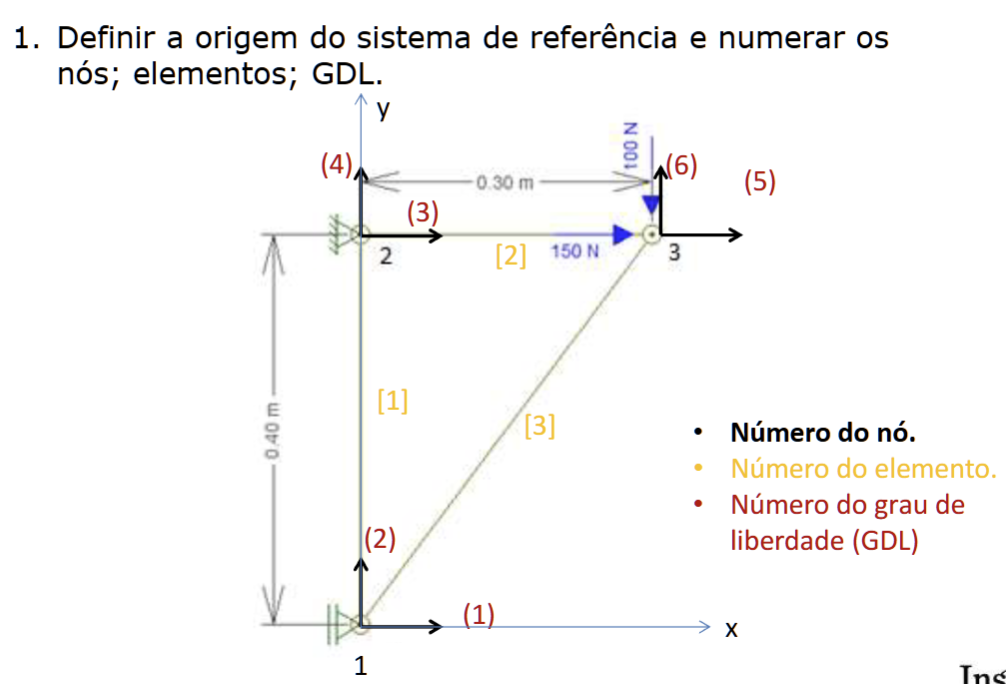

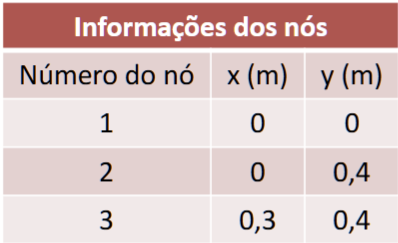

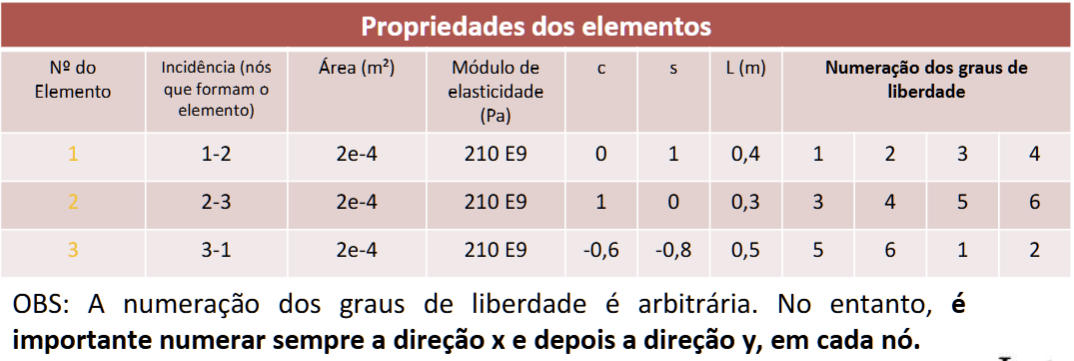

% PASSO 2: Montar a matriz de rigidez de cada elemento
E = 210 * 10^9; % Módulo de elasticidade longitudinal [Pa]
A = 2 * 10^(-4); % Área da seção transversal [m^2]

% X e Y de cada nó
x1 = 0;    y1 = 0;
x2 = 0;    y2 = 0.4;
x3 = 0.3;  y3 = 0.4;

% Comprimento dos elementos (e)
l1 = 0.4;                   % [m]
l2 = 0.3;                   % [m]
l3 = sqrt((l1^2) + (l2^2)); % [m]

% Cossenos (c) e senos (s)
c1 = 0; s1 = 1;
c2 = 1; s2 = 0;
c3 = (x1 - x3)/l3; s3 = (y1 - y3)/l3;

% Matriz de Senos e Cossenos de cada elemento
cos_sens_e1 = [c1^2,    c1*s1, -c1^2,  -c1*s1;
               c1*s1,   s1^2,  -c1*s1, -s1^2;
              -c1^2,   -c1*s1,  c1^2,   c1*s1;
              -c1*s1,  -s1^2,   c1*s1,  s1^2];

cos_sens_e2 = [c2^2,    c2*s2, -c2^2,  -c2*s2;
               c2*s2,   s2^2,  -c2*s2, -s2^2;
              -c2^2,   -c2*s2,  c2^2,   c2*s2;
              -c2*s2,  -s2^2,   c2*s2,  s2^2];

cos_sens_e3 = [c3^2,    c3*s3, -c3^2,  -c3*s3;
               c3*s3,   s3^2,  -c3*s3, -s3^2;
              -c3^2,   -c3*s3,  c3^2,   c3*s3;
              -c3*s3,  -s3^2,   c3*s3,  s3^2];

% Matrizes de Rigidez de cada elemento

K1 = ( E*A ) / l1 * cos_sens_e1;
K2 = ( E*A ) / l2 * cos_sens_e2;
K3 = ( E*A ) / l3 * cos_sens_e3

K3 = 1.0e+07 *

    3.0240    4.0320   -3.0240   -4.0320
    4.0320    5.3760   -4.0320   -5.3760
   -3.0240   -4.0320    3.0240    4.0320
   -4.0320   -5.3760    4.0320    5.3760


ans = -40320000

% PASSO 3: Montar a matriz de rigidez global [Kg] da treliça fazendo asuperposição das matrizes dos elementos.
% Funcionou de primeira 😎
Kg = [K1(1,1) + K3(3,3),  K1(1,2) + K3(3,4),  K1(1,3),            K1(1,4),            K3(3,1),           K3(3,2);
      K1(2,1) + K3(4,3),  K1(2,2) + K3(4,4),  K1(2,3),            K1(2,4),            K3(4,1),           K3(4,2);

      K1(3,1),            K1(3,2),            K1(3,3) + K2(1,1),  K1(3,4) + K2(1,2),  K2(1,3),           K2(1,4);
      K1(4,1),            K1(4,2),            K1(4,3) + K2(2,1),  K1(4,4) + K2(2,2),  K2(2,3),           K2(2,4);

      K3(1,3),            K3(1,4),            K2(3,1),            K2(3,2),            K2(3,3) + K3(1,1), K2(3,4) + K3(1,2);
      K3(2,3),            K3(2,4),            K2(4,1),            K2(4,2),            K2(4,3) + K3(2,1), K2(4,4) + K3(2,2)];

Kg = 1.0e+08 *

    0.3024    0.4032         0         0   -0.3024   -0.4032
    0.4032    1.5876         0   -1.0500   -0.4032   -0.5376
         0         0    1.4000         0   -1.4000         0
         0   -1.0500         0    1.0500         0         0
   -0.3024   -0.4032   -1.4000         0    1.7024    0.4032
   -0.4032   -0.5376         0         0    0.4032    0.5376
